%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Authors      :-  Manas Kumar Mishra, Niranjana Vannadil 
% Project name :-  SEA (Statistical Enhancement of Audio)
% Organization :-  IIITDM Kancheepuram
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Noisy clips
% 1. TempleNoisyclip1_Agra.mp3
% 2. TempleNoisyclip2_Agra.mp3
% 3. TempleNoisyclip1_Agra.wav
% 4. TempleNoisyclip2_Agra.wav
% 5. TestAudio4.wav

[samples, fsample] = audioread('TestSongs/TestAudio4.wav');

player = audioplayer(samples, fsample);
play(player);

fsample %sampling frequency of audio 

fsample = 44100

samples; %Samples, right and left channel



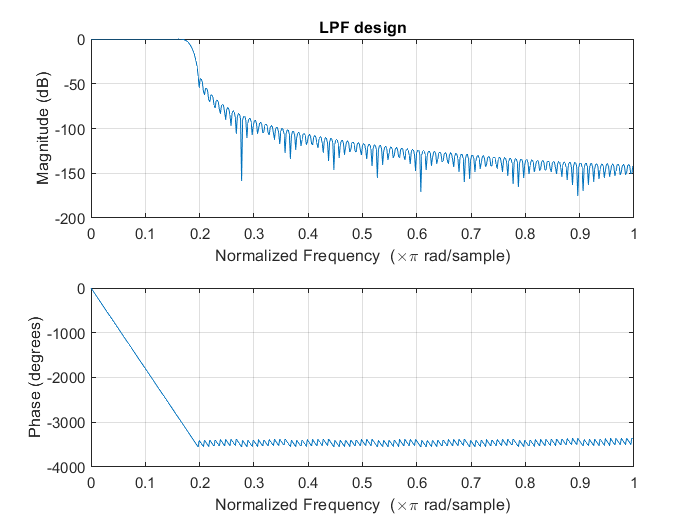

% Preprocessing step
Cutoff = 0.182;

filterLength =200;

filterCoff = impulseResponseOfFilterLPF(Cutoff, filterLength, 3);

NewSamples = myFIRFilter(samples, filterCoff);


player = audioplayer(NewSamples, fsample);
play(player);


% player = audioplayer(Output, fsample);
% play(player);